# Signals during Valsalva and Muller maneuvers

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter4/Maneuvers'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Plotting signals from PNEUMA

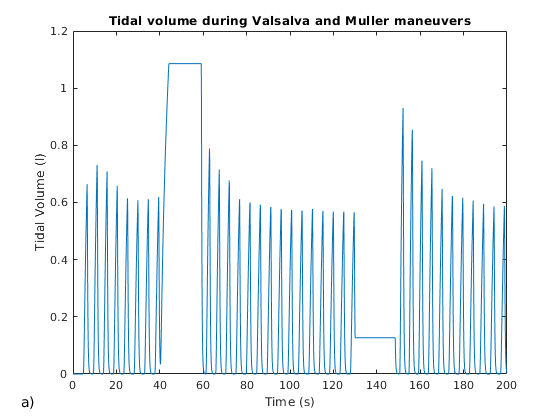

% This function plots the signal from the pneuma simulator stored in the
% file CARDIORESPIRATORY1.mat. The variables include: Time, State Drive SI, HR, ABP, Ppl, PaCO2,
% SaO2, Breathing Frequency BF, Tidal Volume Vt,
% Total Ventilatory Drive DTotal

load('CARDIORESPIRATORY1.mat', 'CARDIORESPIRATORY')
figure
plot(CARDIORESPIRATORY(1,:),CARDIORESPIRATORY(9,:))
xlabel('Time (s)')
ylabel('Tidal Volume (l)')
title('Tidal volume during Valsalva and Muller maneuvers')
annonation_save('a)',"Fig4.2a.jpg", SAVE_FLAG);

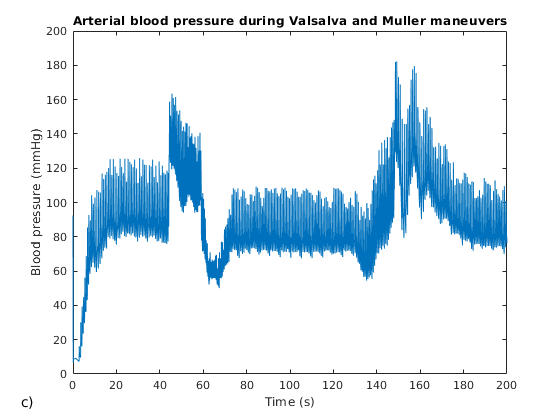

figure
plot(CARDIORESPIRATORY(1,:),CARDIORESPIRATORY(4,:))
xlabel('Time (s)')
ylabel('Blood pressure (mmHg)')
title('Arterial blood pressure during Valsalva and Muller maneuvers')
annonation_save('c)',"Fig4.2c.jpg", SAVE_FLAG);

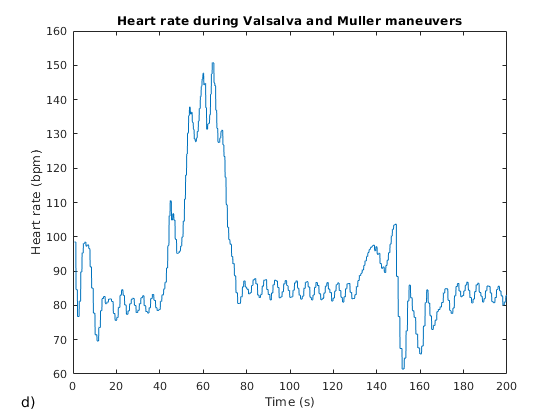

figure
plot(CARDIORESPIRATORY(1,:),CARDIORESPIRATORY(3,:))
xlabel('Time (s)')
ylabel('Heart rate (bpm)')
title('Heart rate during Valsalva and Muller maneuvers')
annonation_save('d)',"Fig4.2d.jpg", SAVE_FLAG);

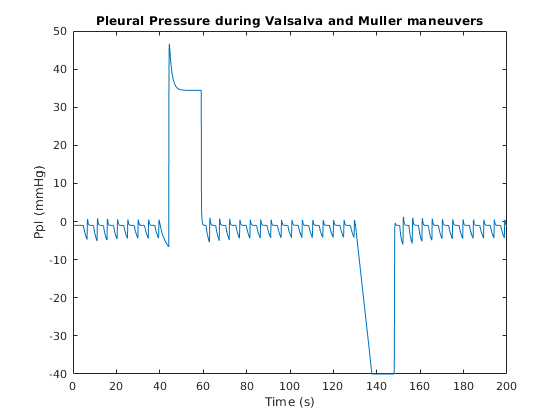

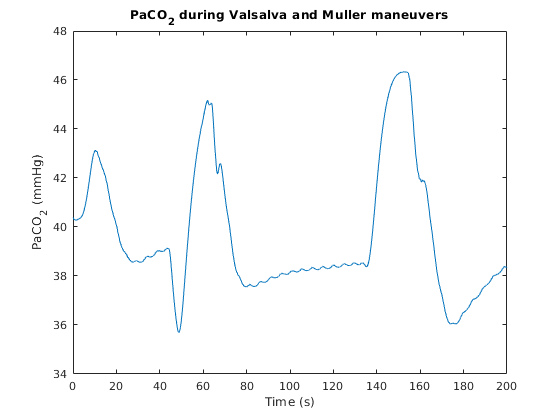

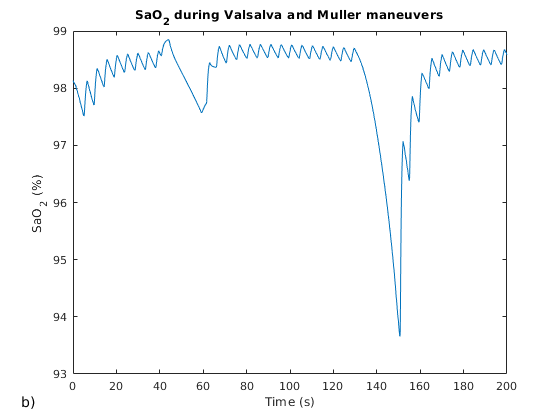

figure
plot(CARDIORESPIRATORY(1,:),CARDIORESPIRATORY(5,:))
xlabel('Time (s)')
ylabel('Ppl (mmHg)')
title('Pleural Pressure during Valsalva and Muller maneuvers')
figure
plot(CARDIORESPIRATORY(1,:),CARDIORESPIRATORY(6,:))
xlabel('Time (s)')
ylabel('PaCO_2 (mmHg)')
title('PaCO_2 during Valsalva and Muller maneuvers')
figure
plot(CARDIORESPIRATORY(1,:),CARDIORESPIRATORY(7,:))
xlabel('Time (s)')
ylabel('SaO_2 (%)')
title('SaO_2 during Valsalva and Muller maneuvers')
annonation_save('b)',"Fig4.2b.jpg", SAVE_FLAG);

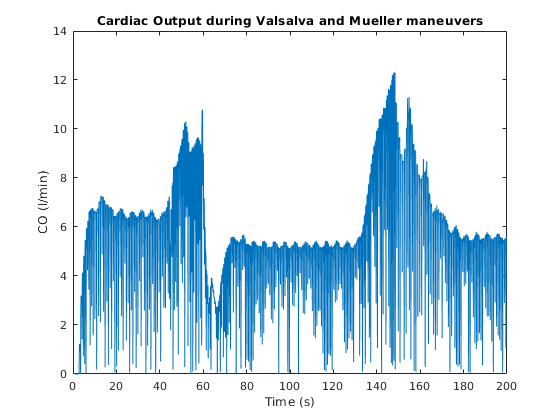


% CARDIO#.mat Cardiovascular System Outputs: Time, Heart Period HP,
% Stroke Volume SV, Cardiac Output CO, TPR and ABP
load('CARDIO1.mat')
figure
plot(CARDIO(1,:),CARDIO(4,:))
xlabel('Time (s)')
ylabel('CO (l/min)')
title('Cardiac Output during Valsalva and Mueller maneuvers')

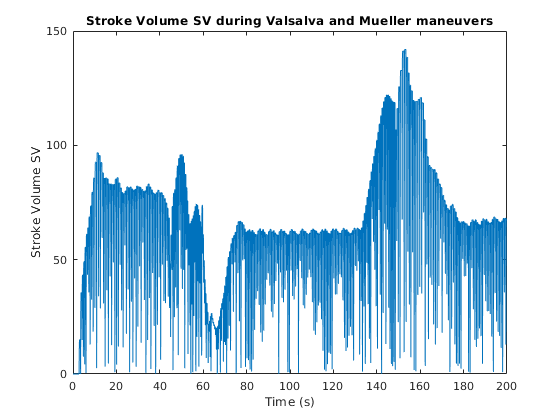



figure
plot(CARDIO(1,:),CARDIO(3,:))
xlabel('Time (s)')
ylabel('Stroke Volume SV')
title('Stroke Volume SV during Valsalva and Mueller maneuvers')